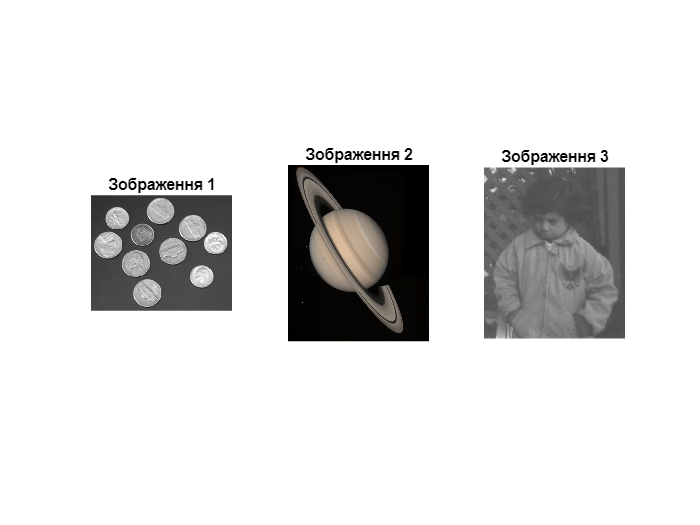

clear, close all

% 1. Завантажив зображення з бібліотеки
a = imread('coins.png');
b = imread('saturn.png');
c = imread('pout.tif');

% 2. Відобразив вихідні зображення
figure (name='Image');
subplot(1,3,1), imshow(a), title('Зображення 1');
subplot(1,3,2), imshow(b), title('Зображення 2');
subplot(1,3,3), imshow(c), title('Зображення 3');

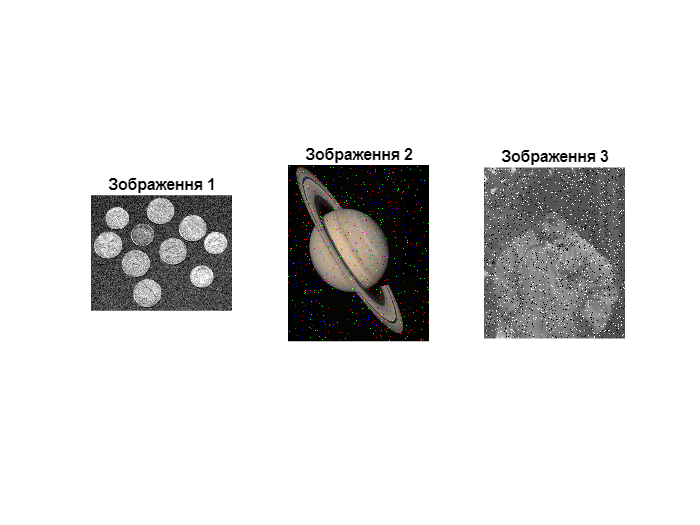


%3. Здійснив процедуру зашумлення зображення нормальним білим шумом і 
% імпульсною перешкодою з різною щільністю.
noise_a = imnoise(a, "gaussian");
noise_b = imnoise(b, "salt & pepper", 0.02);
noise_c = imnoise(c, "salt & pepper", 0.08);

%4. Відобразив зашумлені зображення.
figure (name='Noise');
subplot(1,3,1), imshow(noise_a), title('Зображення 1');
subplot(1,3,2), imshow(noise_b), title('Зображення 2');
subplot(1,3,3), imshow(noise_c), title('Зображення 3');

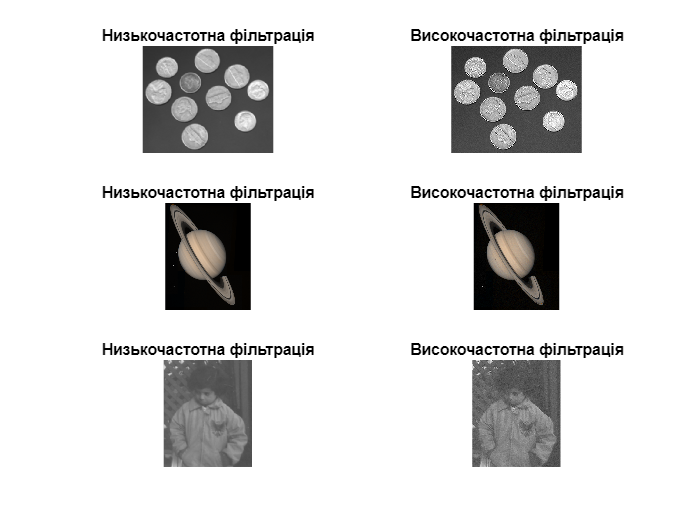


%5. Виконав фільтрацію вихідних зображень лінійними фільтрами з низькими та
%високими частотами

%low_pass = [1, 2, 1; 2, 4, 2; 1, 2, 1] / 16;
%low_pass = [1, 1, 1; 1, 2, 1; 1, 1, 1] / 10;
low_pass = ones(3,3) / 9;

%high_pass = [0, -1, 0; -1, 5, -1; 0, -1, 0];
%high_pass = [-1, -1, -1; -1, 9, -1; -1, -1, -1];
high_pass = [1, -2, 1; -2, 5, -2; 1, -2, 1];

% Застосування фільтрів
a_low = imfilter(a, low_pass);
a_high = imfilter(a, high_pass);
b_low = imfilter(b, low_pass);
b_high = imfilter(b, high_pass);
c_low = imfilter(c, low_pass);
c_high = imfilter(c, high_pass);

%6. Відобразив вихідні зображення після фільтрації
figure (name='Filter clear');
subplot(3,2,1), imshow(a_low), title('Низькочастотна фільтрація');
subplot(3,2,2), imshow(a_high), title('Високочастотна фільтрація');
subplot(3,2,3), imshow(b_low), title('Низькочастотна фільтрація');
subplot(3,2,4), imshow(b_high), title('Високочастотна фільтрація');
subplot(3,2,5), imshow(c_low), title('Низькочастотна фільтрація');
subplot(3,2,6), imshow(c_high), title('Високочастотна фільтрація');

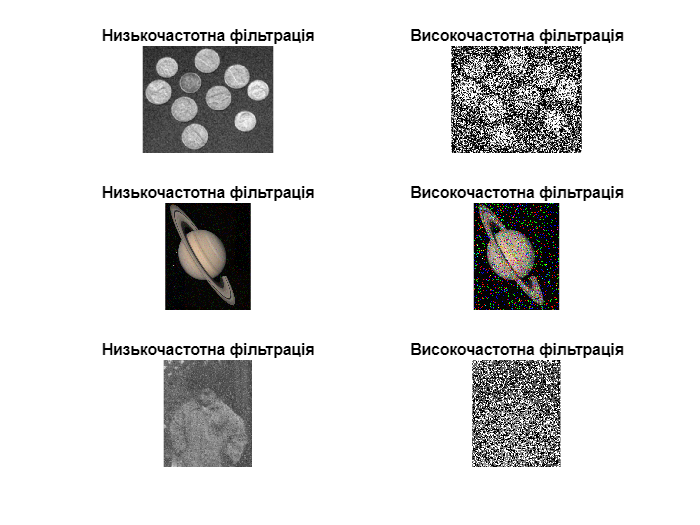


%7. Профільтрував зображення, що зашумлені різними за характером перешкодами.
a_noise_low = imfilter(noise_a, low_pass);
a_noise_high = imfilter(noise_a, high_pass);
b_noise_low = imfilter(noise_b, low_pass);
b_noise_high = imfilter(noise_b, high_pass);
c_noise_low = imfilter(noise_c, low_pass);
c_noise_high = imfilter(noise_c, high_pass);

% Відобразив вихідні зображення після фільтрації
figure (name='Filter noise');
subplot(3,2,1), imshow(a_noise_low), title('Низькочастотна фільтрація');
subplot(3,2,2), imshow(a_noise_high), title('Високочастотна фільтрація');
subplot(3,2,3), imshow(b_noise_low), title('Низькочастотна фільтрація');
subplot(3,2,4), imshow(b_noise_high), title('Високочастотна фільтрація');
subplot(3,2,5), imshow(c_noise_low), title('Низькочастотна фільтрація');
subplot(3,2,6), imshow(c_noise_high), title('Високочастотна фільтрація');

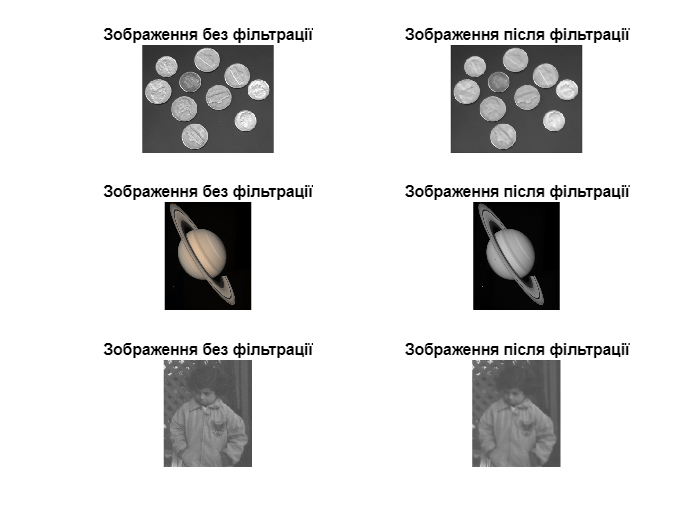


%8. Виконав фільтрацію вихідних і перекручених шумами зображень адаптивним 
% вінерівським фільтром

% Фільтрація вихідних зображень вінерівським фільтром у сірих відтінках
a_w = wiener2(im2gray(a),[5 5]);
b_w = wiener2(im2gray(b),[5 5]);
c_w = wiener2(im2gray(c),[5 5]);

% Фільтрація спотворених зображень вінерівським фільтром у сірих відтінках
a_noise_w = wiener2(im2gray(noise_a),[5 5]);
b_noise_w = wiener2(im2gray(noise_b),[5 5]);
c_noise_w = wiener2(im2gray(noise_c),[5 5]);

% Відображення вихідних зображень після фільтрації вінерівським фільтром
figure (name='Wiener Clear');
subplot(3,2,1), imshow(a), title('Зображення без фільтрації');
subplot(3,2,2), imshow(a_w), title('Зображення після фільтрації');
subplot(3,2,3), imshow(b), title('Зображення без фільтрації');
subplot(3,2,4), imshow(b_w), title('Зображення після фільтрації');
subplot(3,2,5), imshow(c), title('Зображення без фільтрації');
subplot(3,2,6), imshow(c_w), title('Зображення після фільтрації');

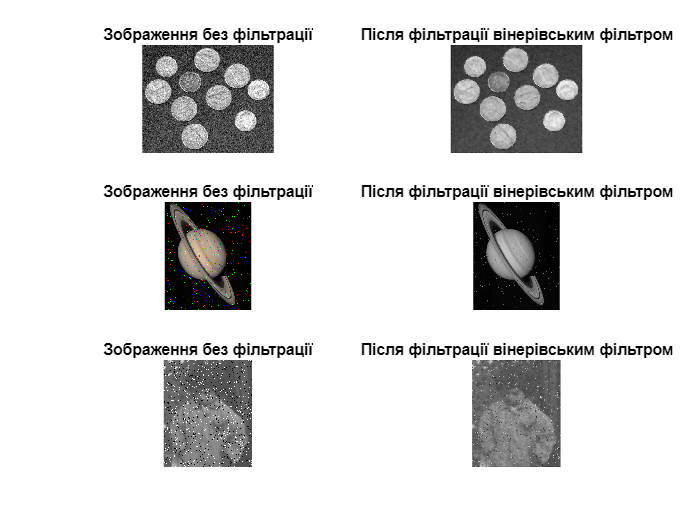


% Відображення спотворених зображень після фільтрації вінерівським фільтром
figure (name='Wiener Noise');
subplot(3,2,1), imshow(noise_a), title('Зображення без фільтрації');
subplot(3,2,2), imshow(a_noise_w), title('Після фільтрації вінерівським фільтром');
subplot(3,2,3), imshow(noise_b), title('Зображення без фільтрації');
subplot(3,2,4), imshow(b_noise_w), title('Після фільтрації вінерівським фільтром');
subplot(3,2,5), imshow(noise_c), title('Зображення без фільтрації');
subplot(3,2,6), imshow(c_noise_w), title('Після фільтрації вінерівським фільтром');

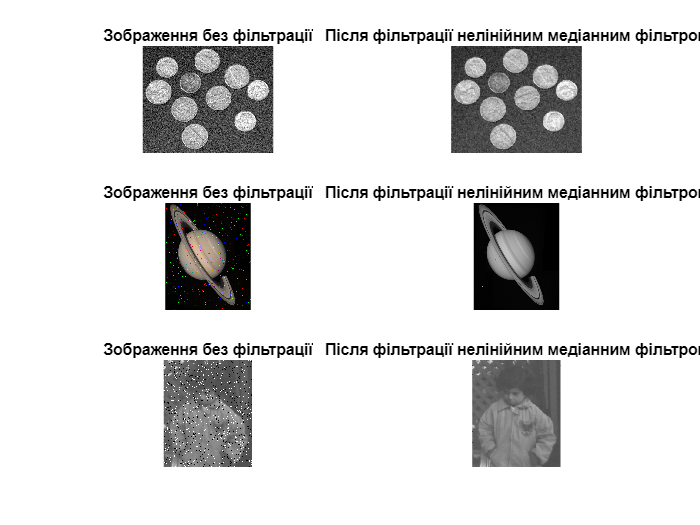


%9. Здійснив фільтрацію зашумлених зображень нелінійним медіанним фільтром у сірих тонах.
a_noise_med = medfilt2(im2gray(noise_a));
b_noise_med = medfilt2(im2gray(noise_b));
c_noise_med = medfilt2(im2gray(noise_c));

figure (name='Medfil Noise');
subplot(3,2,1), imshow(noise_a), title('Зображення без фільтрації');
subplot(3,2,2), imshow(a_noise_med), title('Після фільтрації нелінійним медіанним фільтром');
subplot(3,2,3), imshow(noise_b), title('Зображення без фільтрації');
subplot(3,2,4), imshow(b_noise_med), title('Після фільтрації нелінійним медіанним фільтром');
subplot(3,2,5), imshow(noise_c), title('Зображення без фільтрації');
subplot(3,2,6), imshow(c_noise_med), title('Після фільтрації нелінійним медіанним фільтром');